# Stock Data - Parametric VaR

The 95% parametric Value at Risk (VaR) is the worst daily return one would expect from a stock with a confidence level of 95%. It is calculated by making a fit to the distribution of the stock returns. In this exercise, you will compute the 95% parametric VaR and visualize as two bar series.

## 1. 

Load data from `stockData_allCapSizes.mat`.

load stockData_allCapSizes.mat

## 2.

Extract the stock prices for Magnum Hunter Resources Corporation (ticker: MHR). Calculate the returns for this stock using the following:

`MHRret``= diff(log(MHR))`

MHR = stockPrices.MHR;

% Calculate the returns
MHRret = diff(log(MHR))

MHRret =          0
   -0.0328
    0.0328
   -0.0245
    0.0082
   -0.0165
   -0.0426
         0
   -0.1298
    0.0099


## 3.

Use the `fitdist`function to create a t-Location Scale fit to the MHR returns. Compute the 95% parametric VaR by finding the inverse cumulative density function (ICDF) at a threshold of 0.05.

returnDist = fitdist(MHRret, 'tlocationscale')

returnDist =   tLocationScaleDistribution

  t Location-Scale distribution
       mu = -0.00184679   [-0.0042419, 0.000548319]
    sigma =   0.0346898   [0.0319029, 0.0377202]
       nu =     2.19468   [1.86291, 2.58554]



alpha = 0.05;                   % 5 percent risk
pVaR = icdf(returnDist, 0.05)

pVaR = -0.0973

## 4.

Return two outputs (the bin counts and edges) from the `histcounts`function (use 50 bins). Compute the center of each bin from the bin edges, and then identify the bin centers that are less than the 95% VaRfound in step 3.

[binCounts, binEdges] = histcounts(MHRret, 50);
binCenters = (binEdges(1:end-1) + binEdges(2:end))/2;
% Find which bins are lower than VaR.
lowerVaR = binCenters < pVaR;

## 5. 

Create two bar series to visualize the returns below the VaRin red, and the returns above the VaRin green. Display the VaRvalue in the title of the bar chart.

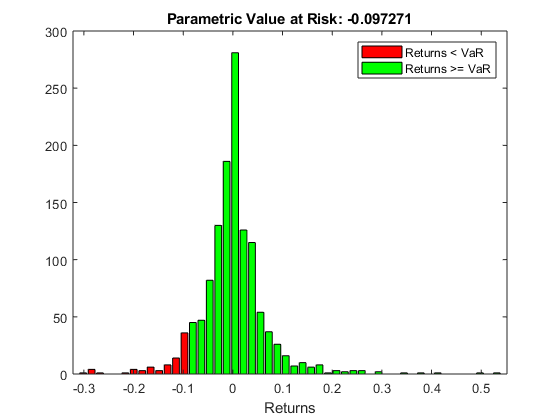

bar(binCenters(lowerVaR), binCounts(lowerVaR), 'r')
hold on
bar(binCenters(~lowerVaR), binCounts(~lowerVaR), 'g')
xlabel('Returns')
title(['Parametric Value at Risk: ', num2str(pVaR)])
legend('Returns < VaR', 'Returns >= VaR')